# Constant False Alarm Rate (CFAR) Detection

This example introduces constant false alarm rate (CFAR) detection and shows how to use CFARDetector and CFARDetector2D in the Phased Array System Toolbox™ to perform cell averaging CFAR detection.

## Introduction

雷达系统执行的一项重要任务是目标检测。检测本身相当简单。它将信号与阈值进行比较。因此，检测的真正工作是提出一个适当的阈值。一般来说，阈值是检测概率和误报概率的函数。在许多相控阵系统中，由于与错误检测相关的成本，希望有一个检测阈值，不仅使检测概率最大化，而且使误报概率保持在预设水平以下。关于如何确定检测阈值，有大量文献。读者可能对白高斯噪声中的信号检测和使用多个样本的信号检测示例感兴趣，以了解一些众所周知的结果。然而，所有这些经典结果都基于理论概率，仅限于已知方差（功率）的白高斯噪声。在实际应用中，噪声通常是彩色的，其功率是未知的。CFAR技术解决了这些问题。在CFAR中，当需要对给定单元（通常称为受试单元（CUT））进行检测时，会根据相邻单元估计噪声功率。然后，检测阈值由下式给出


$$T = \alpha P_n$$


其中， $P_n$是噪声功率估计值， 是称为阈值因子的缩放因子。从等式中可以清楚地看出，阈值适应数据。可以证明，使用适当的阈值因子，可以将误报概率保持恒定，因此称为CFAR。

## Cell Averaging CFAR Detection

单元平均CFAR检测器可能是使用最广泛的CFAR检测器。它也被用作其他CFAR技术的基线比较。在单元平均CFAR检测器中，从CUT周围的前导和滞后单元（称为训练单元）中提取噪声样本。噪声估计可以计算为[1]


$$ P_n = \frac{1}{N}\sum_{m=1}^N x_m $$


其中，$N$是训练单元的数量，$x_m$是每个训练单元中的样本。如果$x_m$恰好是平方律检测器的输出，则$P_n$表示估计的噪声功率。通常，超前和滞后训练单元的数量是相同的。保护单元位于切割单元附近，超前和滞后。这些保护单元的目的是避免信号分量泄漏到训练单元中，这可能会对噪声估计产生不利影响。

下图显示了1-D情况下这些单元之间的关系。

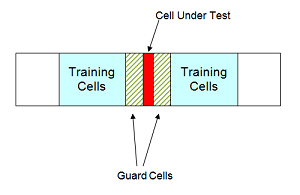

With the above cell averaging CFAR detector, assuming the data passed into the detector is from a single pulse, i.e., no pulse integration involved, the threshold factor can be written as [1]


$$\alpha = N(P_{fa}^{-1/N}-1)$$


where $P_{fa}$ is the desired false alarm rate.

## CFAR Detection Using Automatic Threshold Factor

在本例的其余部分，我们将展示如何使用相控阵系统工具箱进行单元平均恒虚警检测。为了简单起见，并且不失一般性，我们仍然假设噪声是高斯白噪声。这使得可以在恒虚警检测和经典检测理论之间进行比较。

我们可以使用以下命令实例化CFAR检测器：

cfar = phased.CFARDetector('NumTrainingCells',20,'NumGuardCells',2);

在这个检测器中，我们总共使用了20个训练单元和2个保护单元。这意味着在CUT的每侧有10个训练单元和1个保护单元。如上所述，如果我们假设信号来自没有脉冲积分的平方律检测器，则可以根据训练单元的数量和所需的误报概率计算阈值。假设所需的误报率为0.001，我们可以按如下方式配置CFAR检测器，以便进行此计算。

exp_pfa = 1e-3;
cfar.ThresholdFactor = 'Auto';
cfar.ProbabilityFalseAlarm = exp_pfa;

The configured CFAR detector is shown below.

cfar

cfar =   phased.CFARDetector with properties:

                   Method: 'CA'
            NumGuardCells: 2
         NumTrainingCells: 20
          ThresholdFactor: 'Auto'
    ProbabilityFalseAlarm: 1.0000e-03
             OutputFormat: 'CUT result'
      ThresholdOutputPort: false
     NoisePowerOutputPort: false


我们现在模拟输入数据。由于重点是展示CFAR检测器可以将虚警率保持在一定值以下，我们只模拟这些单元中的噪声样本。以下是设置：

- The data sequence is 23 samples long, and the CUT is cell 12. This leaves 10 training cells and 1 guard cell on each side of the CUT.

- The false alarm rate is calculated using 100 thousand Monte Carlo trials.

rs = RandStream('mt19937ar','Seed',2010);
npower = db2pow(-10);  % Assume 10dB SNR ratio

Ntrials = 1e5;
Ncells = 23;
CUTIdx = 12;

% Noise samples after a square law detector
rsamp = randn(rs,Ncells,Ntrials)+1i*randn(rs,Ncells,Ntrials);   
x = abs(sqrt(npower/2)*rsamp).^2;

为了执行检测，将数据传递给检测器。在这个例子中，只有一个CUT，因此输出是一个逻辑向量，包含所有试验的检测结果。如果结果为真，则意味着在相应的试验中存在目标。在我们的例子中，所有检测都是误报，因为我们只传递了噪声。然后可以根据误报数量和试验数量计算出误报率。

x_detected = cfar(x,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 9.4000e-04

The result shows that the resulting probability of false alarm is below 0.001, just as we specified.

## CFAR Detection Using Custom Threshold Factor

如本例前半部分所述，只有少数情况下，CFAR检测器可以自动计算适当的阈值因子。例如，使用前面的场景，如果在数据进入检测器之前使用10个脉冲的非相干积分，自动阈值将不再能提供所需的虚警率。

npower = db2pow(-10);  % Assume 10dB SNR ratio
xn = 0;
for m = 1:10
    rsamp = randn(rs,Ncells,Ntrials)+1i*randn(rs,Ncells,Ntrials);
    xn = xn + abs(sqrt(npower/2)*rsamp).^2;   % noncoherent integration
end
x_detected = cfar(xn,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 0

One may be puzzled why we think a resulting false alarm rate of 0 is worse than a false alarm rate of 0.001. After all, isn't a false alarm rate of 0 a great thing? The answer to this question lies in the fact that when the probability of false alarm is decreased, so is the probability of detection. In this case, because the true false alarm rate is far below the allowed value, the detection threshold is set too high. The same probability of detection can be achieved with our desired probability of false alarm at lower cost; for example, with lower transmitter power.

In most cases, the threshold factor needs to be estimated based on the specific environment and system configuration. We can configure the CFAR detector to use a custom threshold factor, as shown below.

release(cfar);
cfar.ThresholdFactor = 'Custom';

Continuing with the pulse integration example and using empirical data, we found that we can use a custom threshold factor of 2.35 to achieve the desired false alarm rate. Using this threshold, we see that the resulting false alarm rate matches the expected value.

cfar.CustomThresholdFactor = 2.35;
x_detected = cfar(xn,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 9.6000e-04

## CFAR Detection Threshold

A CFAR detection occurs when the input signal level in a cell exceeds the threshold level. The threshold level for each cell depends on the threshold factor and the noise power in that derived from training cells. To maintain a constant false alarm rate, the detection threshold will increase or decrease in proportion to the noise power in the training cells. Configure the CFAR detector to output the threshold used for each detection using the `ThresholdOutputPort` property. Use an automatic threshold factor and 200 training cells.

release(cfar);
cfar.ThresholdOutputPort = true;
cfar.ThresholdFactor = 'Auto';
cfar.NumTrainingCells = 200;

Next, create a square-law input signal with increasing noise power.

rs = RandStream('mt19937ar','Seed',2010);
Npoints = 1e4;
rsamp = randn(rs,Npoints,1)+1i*randn(rs,Npoints,1);
ramp = linspace(1,10,Npoints)';
xRamp = abs(sqrt(npower*ramp./2).*rsamp).^2;

Compute detections and thresholds for all cells in the signal.

[x_detected,th] = cfar(xRamp,1:length(xRamp));

Next, compare the CFAR threshold to the input signal.

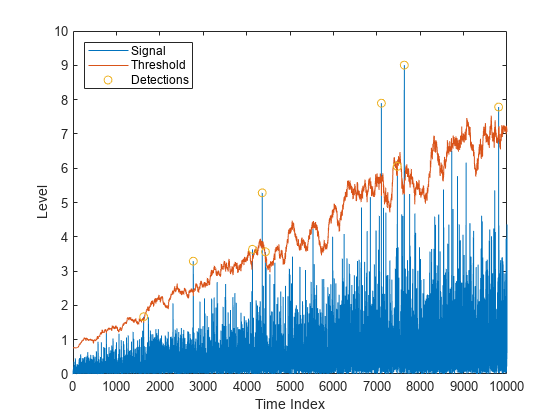

plot(1:length(xRamp),xRamp,1:length(xRamp),th,...
  find(x_detected),xRamp(x_detected),'o')
legend('Signal','Threshold','Detections','Location','Northwest')
xlabel('Time Index')
ylabel('Level')

Here, the threshold increases with the noise power of the signal to maintain the constant false alarm rate. Detections occur where the signal level exceeds the threshold.

## Comparison Between CFAR and Classical Neyman-Pearson Detector

在本节中，我们将使用Neyman-Pearson原理比较CFAR检测器与经典检测理论的性能。回到第一个例子，假设已知真实噪声功率，理论阈值可以计算为

T_ideal = npower*db2pow(npwgnthresh(exp_pfa));

The false alarm rate of this classical Neyman-Pearson detector can be calculated using this theoretical threshold.

act_Pfa_np = sum(x(CUTIdx,:)>T_ideal)/Ntrials

act_Pfa_np = 9.5000e-04

Because we know the noise power, classical detection theory also produces the desired false alarm rate. The false alarm rate achieved by the CFAR detector is similar.

release(cfar);
cfar.ThresholdOutputPort = false;
cfar.NumTrainingCells = 20;
x_detected = cfar(x,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 9.4000e-04

Next, assume that both detectors are deployed to the field and that the noise power is 1 dB more than expected. In this case, if we use the theoretical threshold, the resulting probability of false alarm is four times more than what we desire.

npower = db2pow(-9);  % Assume 9dB SNR ratio
rsamp = randn(rs,Ncells,Ntrials)+1i*randn(rs,Ncells,Ntrials);
x = abs(sqrt(npower/2)*rsamp).^2;   
act_Pfa_np = sum(x(CUTIdx,:)>T_ideal)/Ntrials

act_Pfa_np = 0.0041

On the contrary, the CFAR detector's performance is not affected.

x_detected = cfar(x,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 0.0011

Hence, the CFAR detector is robust to noise power uncertainty and better suited to field applications.

Finally, use a CFAR detection in the presence of colored noise. We first apply the classical detection threshold to the data.

npower = db2pow(-10);
fcoeff = maxflat(10,'sym',0.2);
x = abs(sqrt(npower/2)*filter(fcoeff,1,rsamp)).^2;   % colored noise
act_Pfa_np = sum(x(CUTIdx,:)>T_ideal)/Ntrials

act_Pfa_np = 0

Note that the resulting false alarm rate cannot meet the requirement. However, using the CFAR detector with a custom threshold factor, we can obtain the desired false alarm rate.

release(cfar);
cfar.ThresholdFactor = 'Custom';
cfar.CustomThresholdFactor = 12.85;
x_detected = cfar(x,CUTIdx);
act_pfa = sum(x_detected)/Ntrials

act_pfa = 0.0010

## CFAR Detection for Range-Doppler Images

在前面的部分中，噪声估计是从训练单元中计算出来的，这些训练单元在一个维度上领先和滞后于CUT。我们也可以对图像进行CFAR检测。单元对应于图像中的像素，保护单元和训练单元被放置在CUT周围的带中。检测阈值是从CUT周围的矩形训练带中的单元计算出来的。

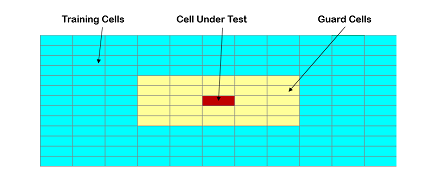

In the figure above, the guard band size is [2 2] and the training band size is [4 3]. The size indices refer to the number of cells on each side of the CUT in the row and columns dimensions, respectively. The guard band size can also be defined as 2, since the size is the same along row and column dimensions.

Next, create a two-dimensional CFAR detector. Use a probability of false alarm of 1e-5 and specify a guard band size of 5 cells and a training band size of 10 cells.

cfar2D = phased.CFARDetector2D('GuardBandSize',5,'TrainingBandSize',10,...
  'ProbabilityFalseAlarm',1e-5);

Next, load and plot a range-doppler image. The image includes returns from two stationary targets and one target moving away from the radar.

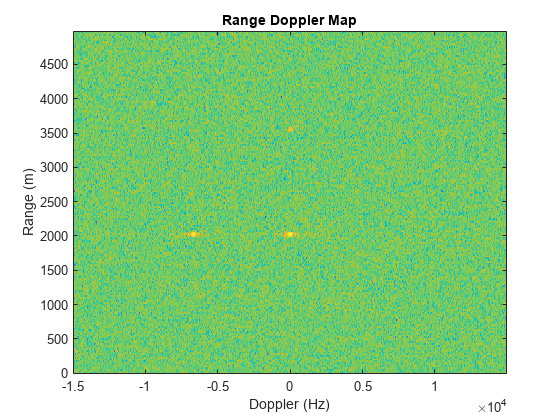

[resp,rngGrid,dopGrid] = helperRangeDoppler;

Use CFAR to search the range-Doppler space for objects, and plot a map of the detections. Search from -10 to 10 kHz and from 1000 to 4000 m. First, define the cells under test for this region.

[~,rangeIndx] = min(abs(rngGrid-[1000 4000]));
[~,dopplerIndx] = min(abs(dopGrid-[-1e4 1e4]));
[columnInds,rowInds] = meshgrid(dopplerIndx(1):dopplerIndx(2),...
  rangeIndx(1):rangeIndx(2));
CUTIdx = [rowInds(:) columnInds(:)]';

Compute a detection result for each cell under test. Each pixel in the search region is a cell in this example. Plot a map of the detection results for the range-Doppler image.

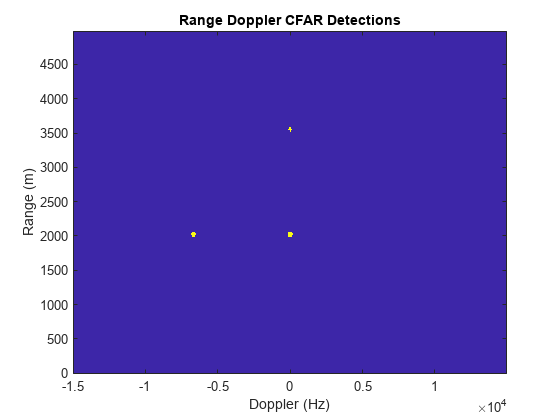

detections = cfar2D(resp,CUTIdx);
helperDetectionsMap(resp,rngGrid,dopGrid,rangeIndx,dopplerIndx,detections)

The three objects are detected. A data cube of range-Doppler images over time can likewise be provided as the input signal to `cfar2D`, and detections will be calculated in a single step.

## Summary

在这个例子中，我们介绍了CFAR检测器背后的基本概念。特别是，我们探索了如何使用相控阵系统工具箱对信号和距离多普勒图像进行单元平均CFAR检测。单元平均CFAR检测器和配备有理论计算阈值的检测器之间的性能比较清楚地表明，CFAR检测器更适合实际现场应用。

## Reference

[1] Mark Richards, *Fundamentals of Radar Signal Processing*, McGraw Hill, 2005

*Copyright 2010-2017 The MathWorks, Inc.*